% 生成从30MHz到32.5MHz的线性调频信号
f0 = 500e6; % 初始频率
Tc = 2e-6; % 信号持续时间
T = 2e-3; % 信号重复周期
F = 1e8; % 离散频率
Fs = 5e6;%采样率
t = 0:1/F:T; % 时间向量
SNR = -20; % Signal to noise ratio (dB)
A = 0.2;% 信号衰减
Distance = 150e3;% 距离(m)
c = 3e8;% 光速
Dealy_Time = 2*Distance/c%信号返回滞后时间

Dealy_Time = 1.0000e-03

x_rec = A * sinc(2*pi/Tc*(t-Dealy_Time)); % 接收信号向量

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =    -0.0260    0.0002   -0.0255   -0.0198   -0.0153    0.0291    0.0381    0.0161    0.0092   -0.0043   -0.0038    0.0337    0.0065   -0.0021    0.0156    0.0107    0.0277    0.0156   -0.0191    0.0023   -0.0122    0.0039    0.0581    0.0270    0.0635   -0.0077   -0.0006    0.0202   -0.0086    0.0042    0.0191    0.0060    0.0151   -0.0243    0.0423    0.0275    0.0005    0.0040    0.0424   -0.0411   -0.0448   -0.0395   -0.0010   -0.0289    0.0112   -0.0403   -0.0149   -0.0126   -0.0196   -0.0223


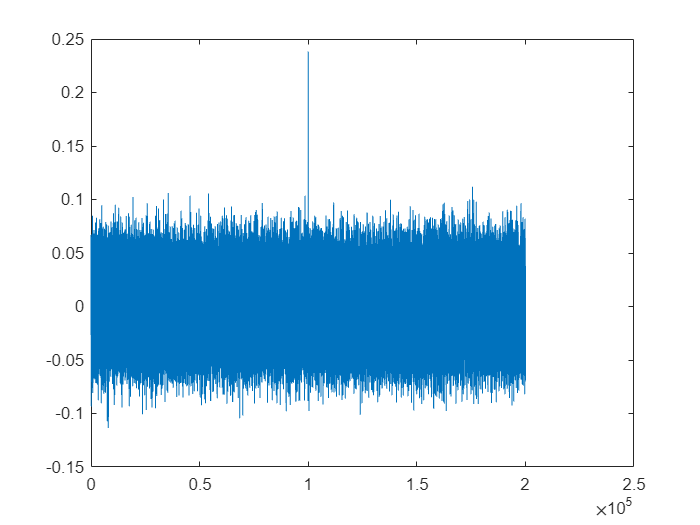

plot(x_awgn);

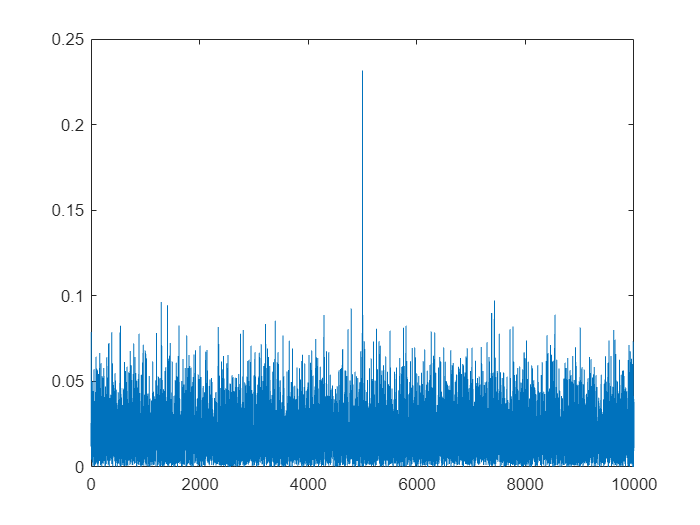

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_1.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =     0.0056   -0.0285   -0.0067   -0.0264    0.0477   -0.0090   -0.0062    0.0204   -0.0212   -0.0265    0.0080    0.0298   -0.0267    0.0108   -0.0168   -0.0135   -0.0389    0.0234    0.0423   -0.0454   -0.0042    0.0133    0.0111    0.0145    0.0064   -0.0188   -0.0109   -0.0331    0.0488   -0.0200   -0.0199   -0.0016    0.0437    0.0034    0.0163    0.0095   -0.0208    0.0260   -0.0186   -0.0078    0.0076    0.0062    0.0169    0.0189   -0.0156   -0.0306    0.0438    0.0084   -0.0161    0.0335


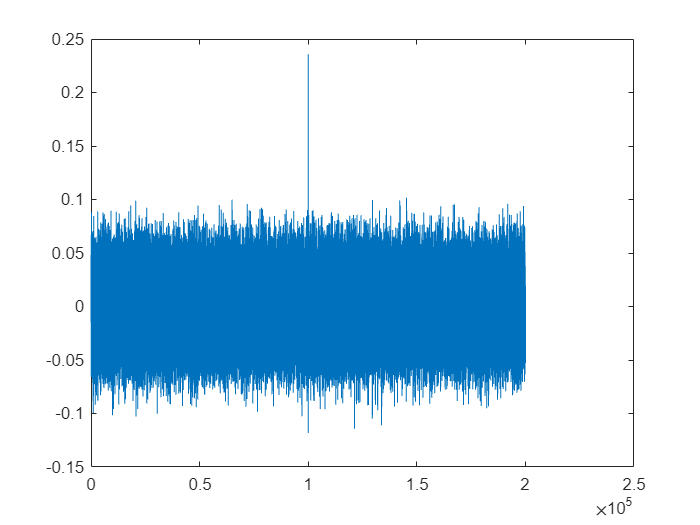

plot(x_awgn);

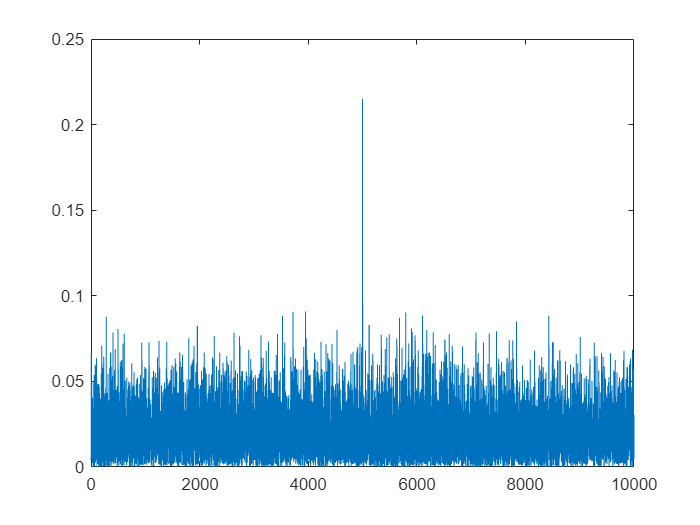

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_2.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =    -0.0041    0.0055   -0.0287    0.0190   -0.0377   -0.0014   -0.0072    0.0361    0.0395    0.0129   -0.0326    0.0341    0.0094    0.0058   -0.0209    0.0160    0.0184    0.0241   -0.0072    0.0040   -0.0652   -0.0181   -0.0333   -0.0298   -0.0102    0.0122    0.0546   -0.0076    0.0440    0.0153   -0.0065    0.0324    0.0270   -0.0045    0.0284   -0.0102   -0.0254   -0.0019   -0.0051   -0.0146    0.0011   -0.0401    0.0356   -0.0455   -0.0305   -0.0214    0.0106    0.0105    0.0048   -0.0093


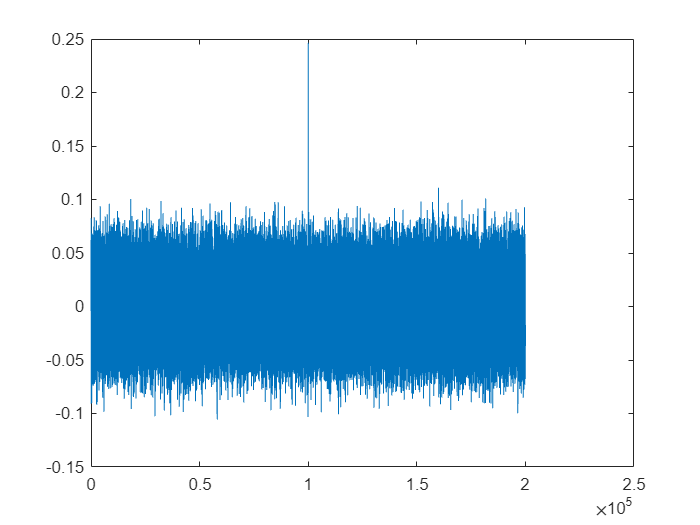

plot(x_awgn);

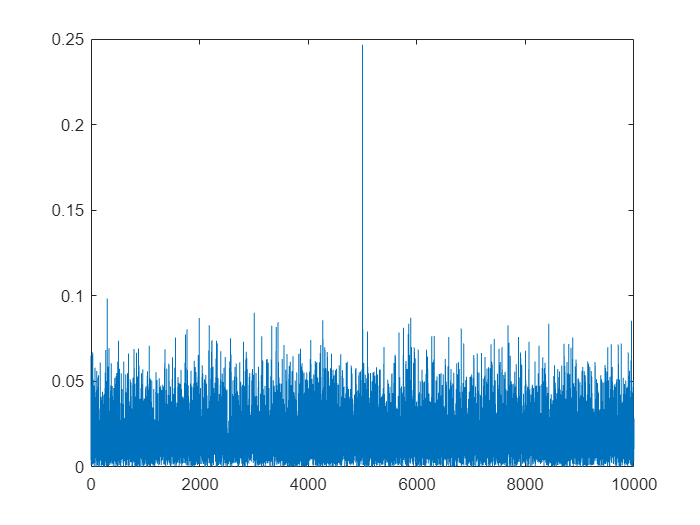

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_3.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =     0.0271    0.0233    0.0504    0.0210    0.0012   -0.0396    0.0412   -0.0036    0.0427    0.0403    0.0332   -0.0312    0.0480   -0.0291   -0.0053   -0.0225    0.0493   -0.0134   -0.0054   -0.0014   -0.0137   -0.0145    0.0047    0.0187   -0.0006    0.0273    0.0162   -0.0405    0.0080    0.0275   -0.0233    0.0183   -0.0316    0.0157    0.0001   -0.0301   -0.0227    0.0020    0.0074    0.0205    0.0223   -0.0399    0.0111    0.0069   -0.0046    0.0013    0.0326    0.0328    0.0274    0.0392


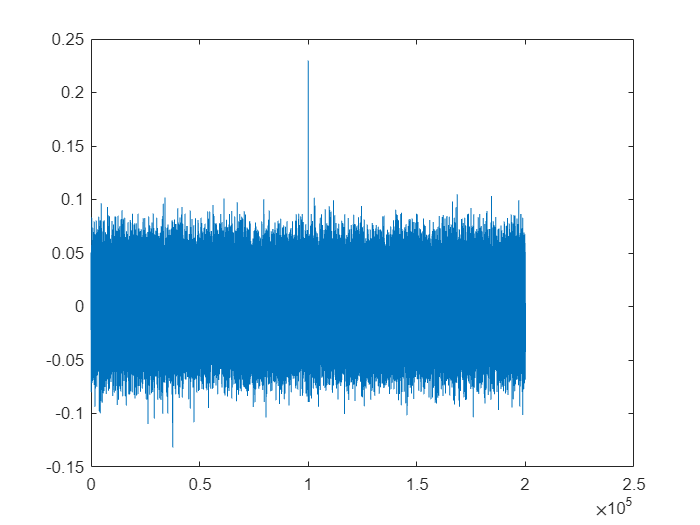

plot(x_awgn);

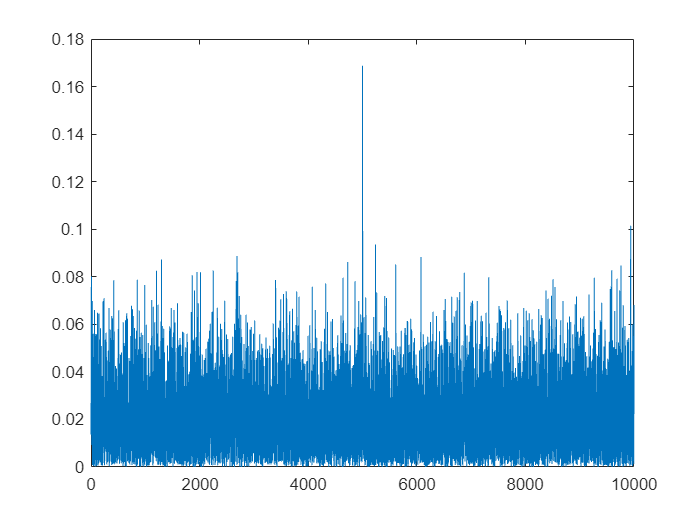

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_4.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =     0.0105   -0.0346   -0.0314   -0.0197    0.0044   -0.0055   -0.0090   -0.0082   -0.0178    0.0279    0.0318   -0.0185   -0.0387   -0.0172    0.0342    0.0032   -0.0248    0.0052    0.0346    0.0229    0.0107   -0.0155    0.0280    0.0012    0.0088   -0.0043   -0.0278   -0.0111   -0.0057   -0.0619   -0.0261   -0.0185    0.0243   -0.0172    0.0240   -0.0447   -0.0130    0.0234   -0.0068   -0.0360    0.0496    0.0097   -0.0344    0.0140   -0.0178    0.0074    0.0099    0.0121    0.0309   -0.0308


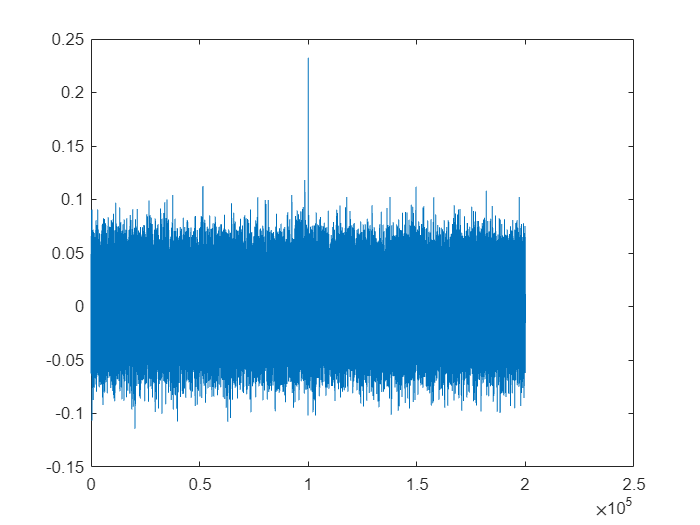

plot(x_awgn);

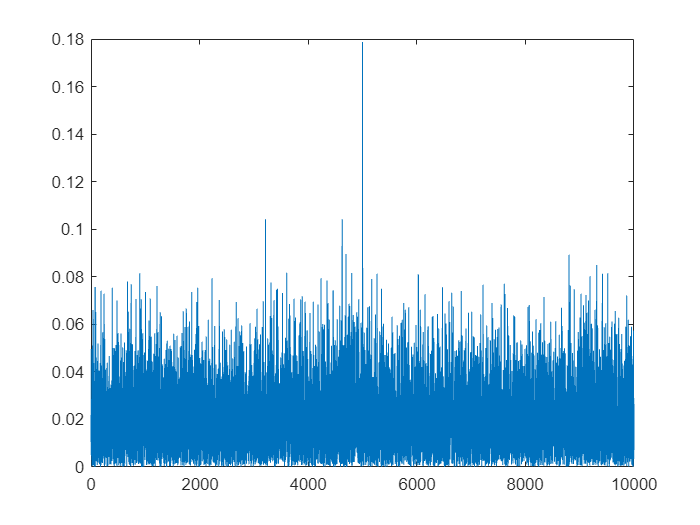

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_5.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =    -0.0073   -0.0190   -0.0309    0.0282    0.0338    0.0305    0.0204   -0.0110   -0.0128   -0.0354    0.0179    0.0038    0.0094   -0.0032    0.0063   -0.0241    0.0558    0.0141    0.0094   -0.0081    0.0210    0.0177   -0.0299   -0.0107   -0.0141    0.0177   -0.0319   -0.0207    0.0151    0.0254   -0.0149   -0.0091   -0.0255    0.0135   -0.0178   -0.0021   -0.0245   -0.0161   -0.0003   -0.0493   -0.0102   -0.0275    0.0250    0.0141   -0.0293    0.0091   -0.0084   -0.0255    0.0340   -0.0206


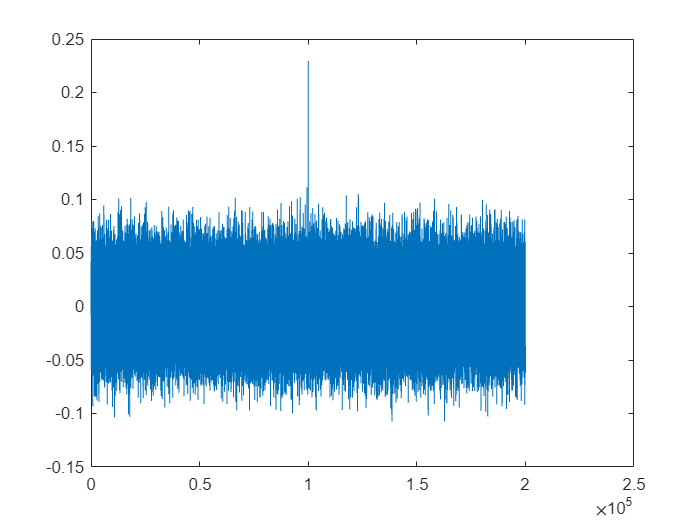

plot(x_awgn);

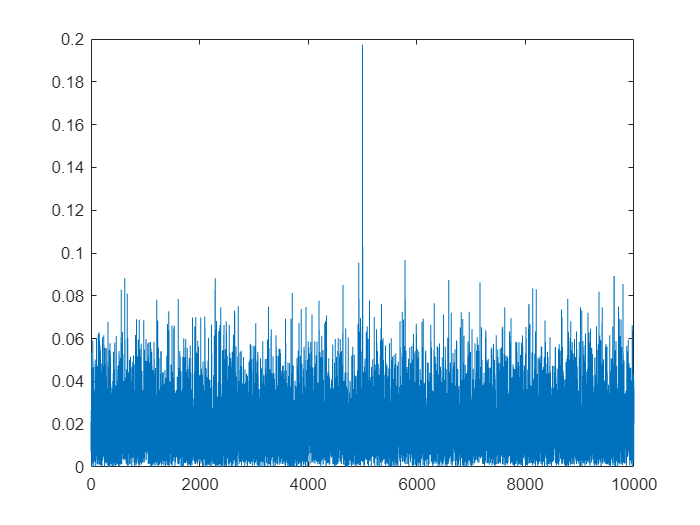

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_6.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =     0.0138    0.0808   -0.0402    0.0051    0.0258    0.0497   -0.0032   -0.0159   -0.0148    0.0149    0.0103   -0.0262   -0.0403   -0.0054   -0.0203   -0.0210    0.0119   -0.0321    0.0466    0.0017   -0.0234   -0.0091   -0.0124   -0.0007   -0.0072    0.0206    0.0134   -0.0236    0.0197    0.0404    0.0112    0.0281   -0.0119    0.0027   -0.0173    0.0413   -0.0076   -0.0089   -0.0234   -0.0488   -0.0259    0.0366   -0.0418   -0.0104    0.0248    0.0051    0.0454   -0.0271   -0.0091    0.0222


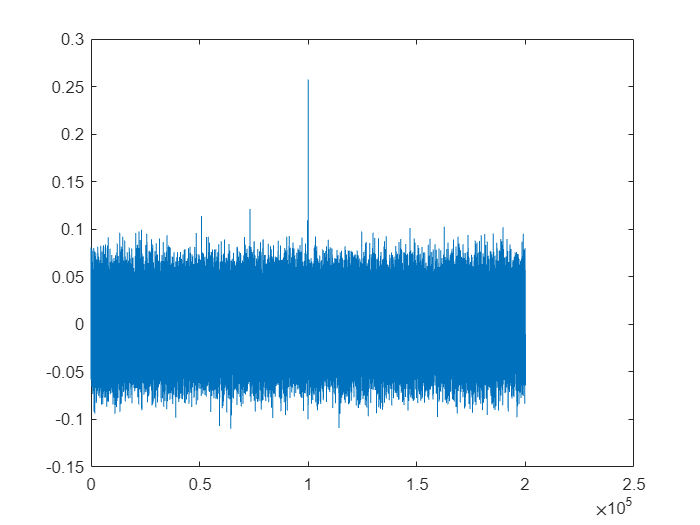

plot(x_awgn);

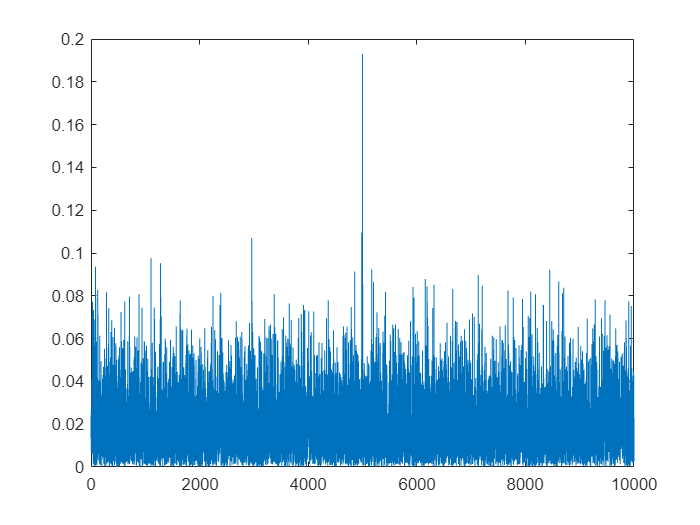

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_7.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =    -0.0090    0.0064    0.0117    0.0379   -0.0205    0.0026    0.0371    0.0244    0.0113    0.0040    0.0106   -0.0129    0.0124    0.0444    0.0160   -0.0411    0.0324    0.0107   -0.0141   -0.0087    0.0401   -0.0192   -0.0021    0.0119    0.0206   -0.0381    0.0001    0.0014    0.0603   -0.0315    0.0183    0.0178   -0.0055   -0.0338   -0.0135    0.0042   -0.0144   -0.0077    0.0252   -0.0432    0.0260   -0.0081    0.0209   -0.0034   -0.0053   -0.0303   -0.0284   -0.0144    0.0199   -0.0044


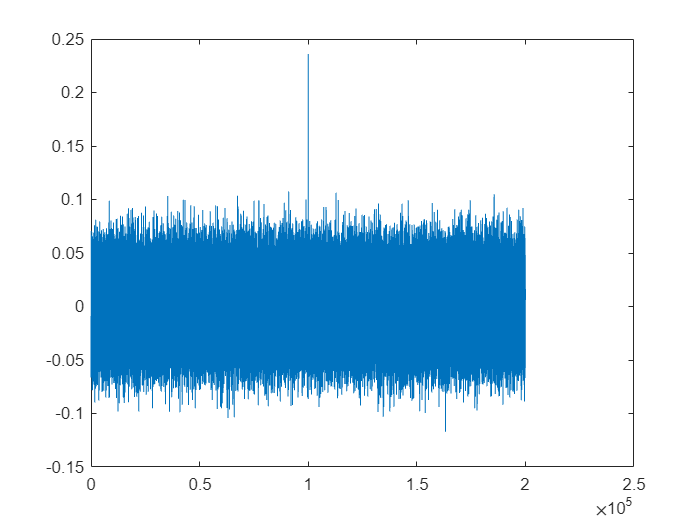

plot(x_awgn);

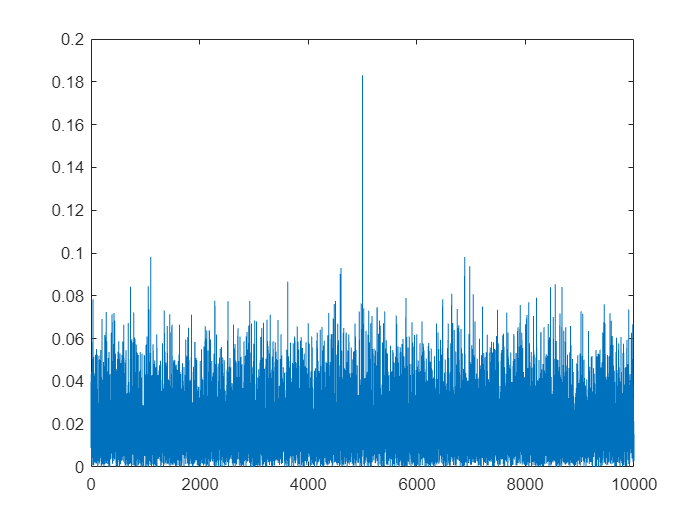

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_8.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =    -0.0094   -0.0366   -0.0418    0.0156    0.0038    0.0009   -0.0306   -0.0207   -0.0160    0.0056    0.0024   -0.0013   -0.0055    0.0158   -0.0328    0.0089   -0.0213    0.0248   -0.0423   -0.0182    0.0170    0.0314    0.0218    0.0089    0.0326    0.0542    0.0269    0.0118   -0.0314    0.0120    0.0098   -0.0027   -0.0053   -0.0243    0.0253   -0.0010   -0.0230   -0.0396    0.0132   -0.0188    0.0003    0.0042   -0.0265   -0.0150   -0.0074   -0.0361   -0.0165    0.0390   -0.0077   -0.0486


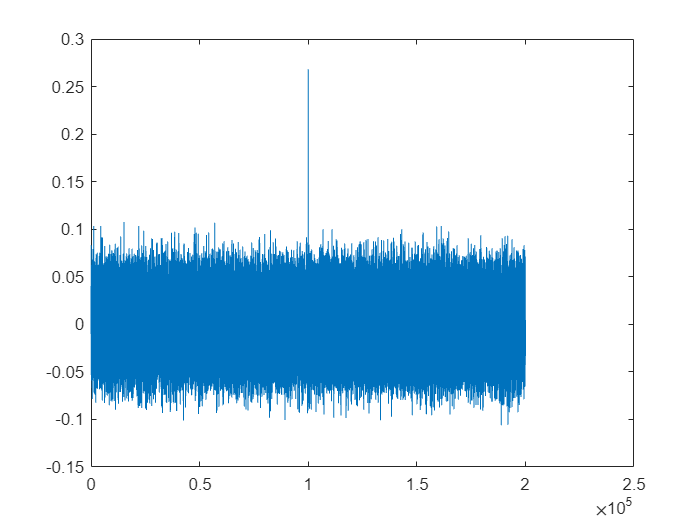

plot(x_awgn);

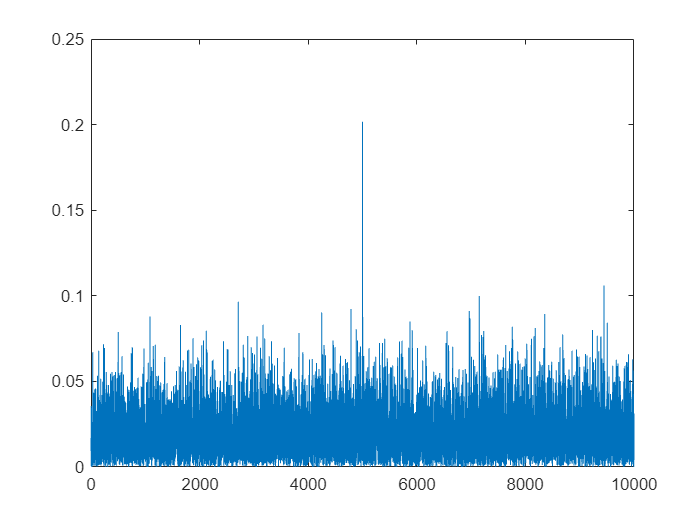

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_9.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件

x_awgn=awgn(x_rec,SNR,'measured') % Simulated signal with AWGN noise

x_awgn =     0.0045   -0.0026   -0.0036   -0.0069   -0.0114   -0.0077    0.0123   -0.0480   -0.0022   -0.0259    0.0037    0.0087    0.0484   -0.0196   -0.0133   -0.0061    0.0133   -0.0225    0.0421   -0.0132   -0.0067   -0.0207    0.0106   -0.0333   -0.0048    0.0169   -0.0004    0.0212   -0.0304    0.0102   -0.0504   -0.0215    0.0223    0.0147   -0.0212   -0.0607    0.0184    0.0122    0.0179   -0.0160    0.0226   -0.0169    0.0074   -0.0080    0.0273   -0.0081    0.0324    0.0376    0.0151    0.0172


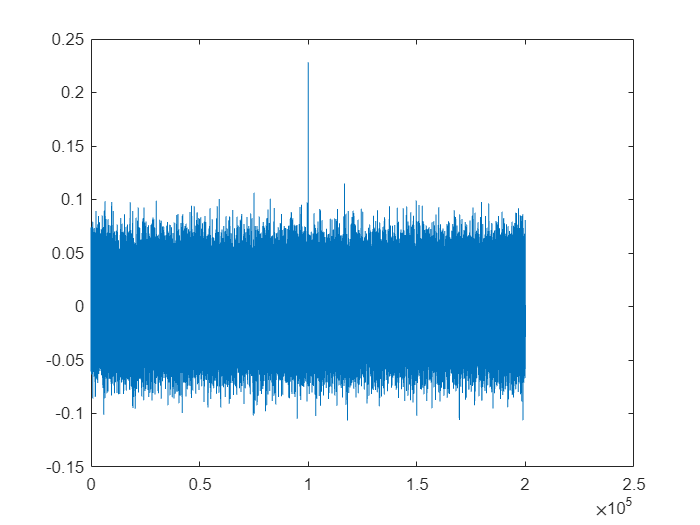

plot(x_awgn);

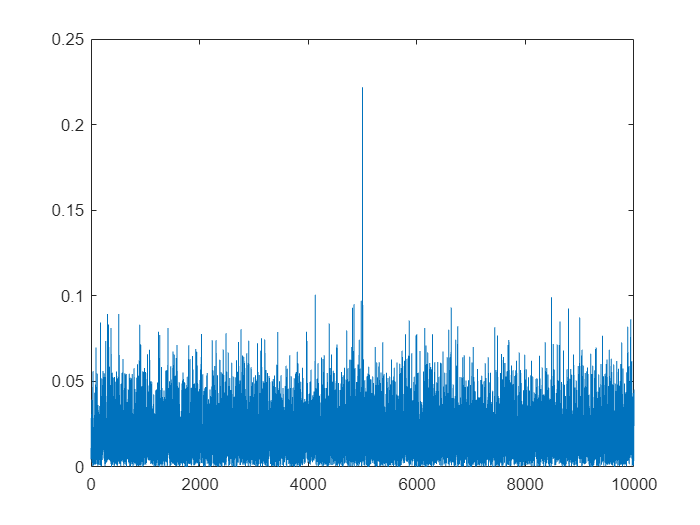

x_ad = abs(x_awgn(1:F/Fs:T*F));
plot(x_ad);

x_append = zeros(1,2^14-length(x_ad));
x_bin = dec2bin(typecast(uint8([x_ad x_append]),'uint8'),8);
% 将二进制数据写入mif文件
fid = fopen('AD_10.mif','w'); % 打开文件
fprintf(fid,'WIDTH=8;\n'); % 写入宽度
fprintf(fid,'DEPTH=%d;\n',length(x_bin)); % 写入深度
fprintf(fid,'ADDRESS_RADIX=UNS;\n'); % 写入地址基数
fprintf(fid,'DATA_RADIX=BIN;\n'); % 写入数据基数
fprintf(fid,'CONTENT BEGIN\n'); % 写入内容开始标志
for i = 1:length(x_bin)
    fprintf(fid,'%d : %s;\n',i-1,x_bin(i,:)); % 写入地址和数据
end
fprintf(fid,'END;\n'); % 写入内容结束标志
fclose(fid); % 关闭文件